# WInner-take-all theory: 1L5E as receiver 

# investigate the layer-dependent activities and interation among populations

% clear;
% close all;
% clc;
% initime = clock;
addpath('../funcs');
figpath = '../../report/figures/';

condition = {'Original', 'Condition: S1', 'Condition: S2','Condition: S1S2','Condition: S1S2+A1','Condition: S1S2+A2'};
titleFont = 20;
layers = {'L2/3', 'L4', 'L5', 'L6'};
colors = ["#EA4335", "#FBBC05", "#4285F4", "#34A853"];

Delta_e = 0.3;
Delta_i = 0.032;
Iattn = 0.02;
allTime = 4000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, allTime);
r = r*1000;
PETC = getPET(v(:,350000:400000,:),g(:,:,350000:400000,:));
PET0 = getPET(v(:,50000:100000,:),g(:,:,50000:100000,:));
PET(:,:,1) = PET0(:,:,1);
PET(:,:,2:6) = PETC;
env = getEnvelope(r);

     1

     1

     1

     1

     1

     2

     2

     2

     2

     2

     3

     3

     3

     3

     3

     4

     4

     4

     4

     4

     5

     5

     5

     5

     5

     6

     6

     6

     6

     6

     7

ENTERED!
     7

ENTERED!
     7

ENTERED!
     7

ENTERED!
     7

ENTERED!
     8

     8

     8

     8

     8

     9

     9

     9

     9

     9

    10

    10

    10

    10

    10

    11

    11

    11

    11

    11

    12

    12

    12

    12

    12

    13

    13

    13

    13

    13

    14

    14

    14

    14

    14

    15

ENTERED!
    15

ENTERED!
    15

ENTERED!
    15

ENTERED!
    15

ENTERED!
    16

    16

    16

    16

    16



% scatter(0.3, 0.027,30, "x","MarkerEdgeColor","k","LineWidth",1);
% scatter(0.3, 0.032,30, "+","MarkerEdgeColor","k","LineWidth",1);


## Firing rate by layers

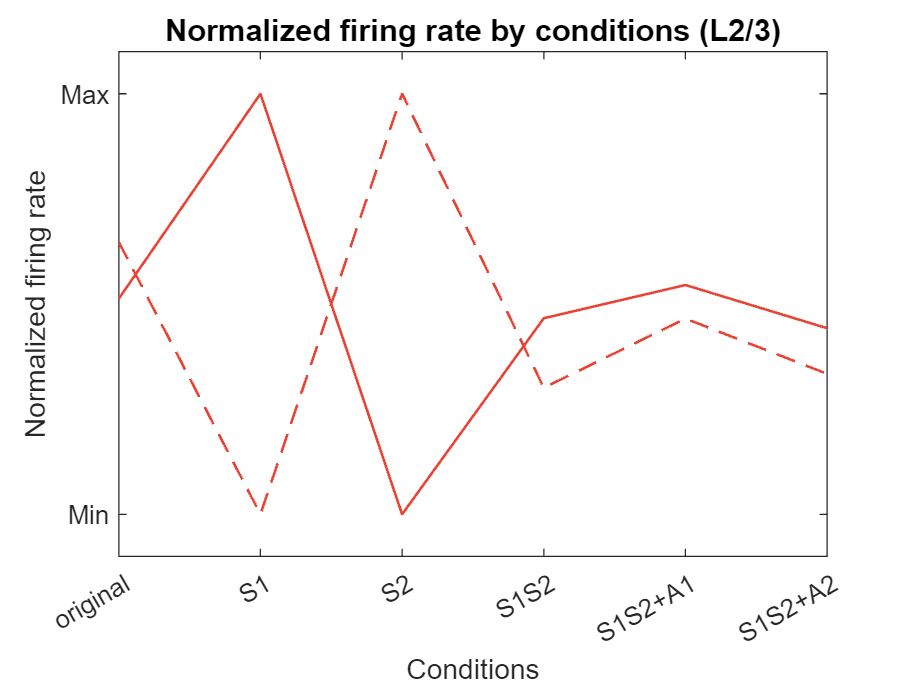

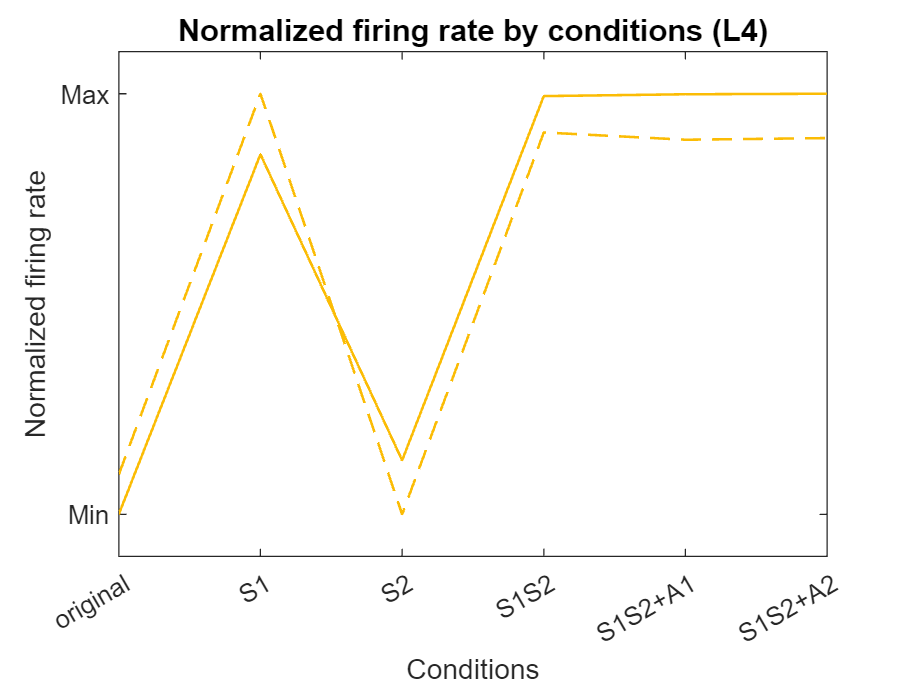

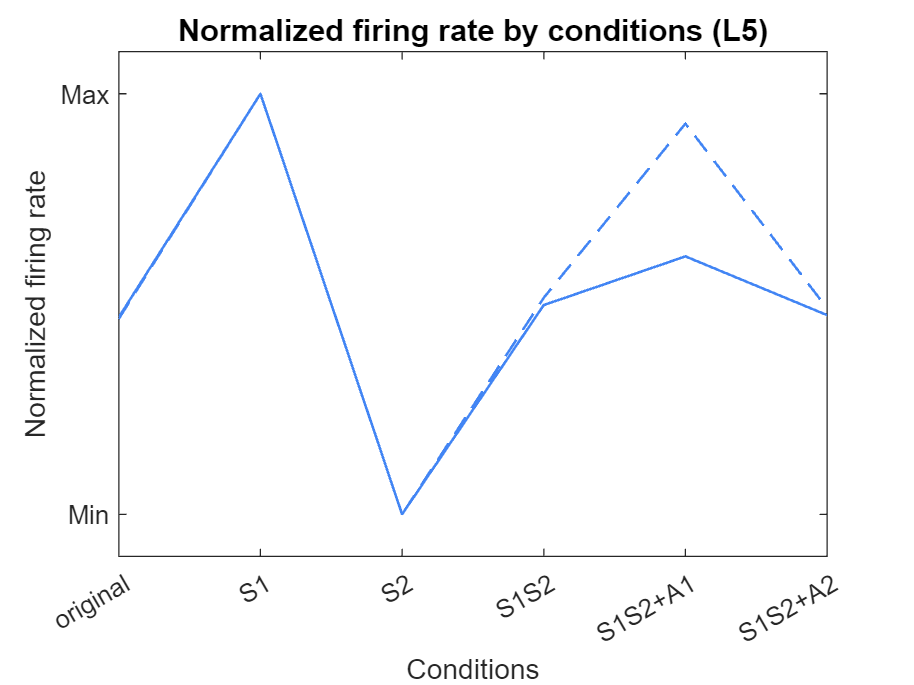

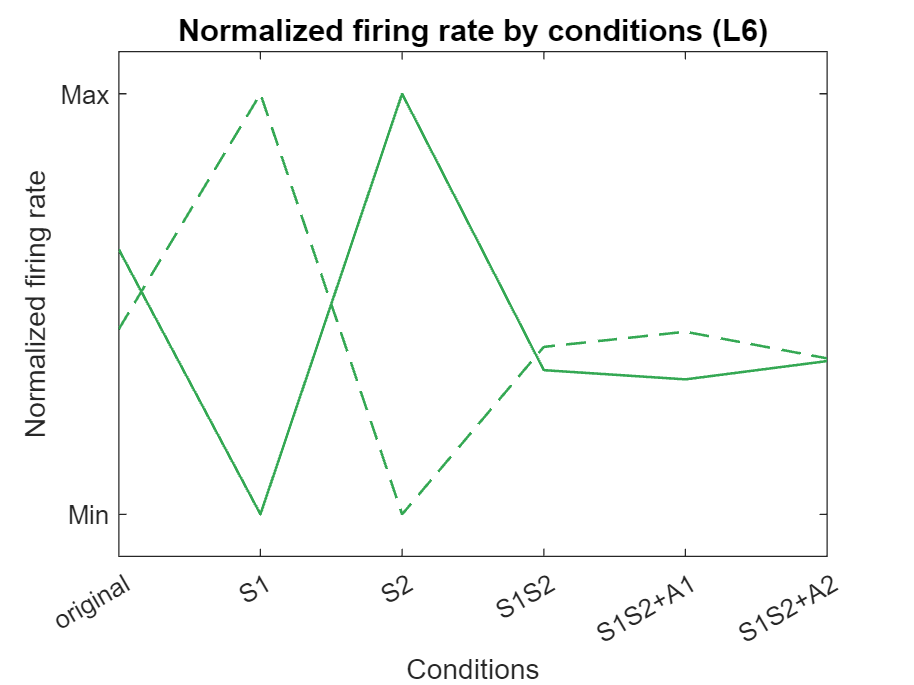

level = getLevel(r, 350000, 400000);
level_norm = normBetween01(level,2);
condax = [1 2 3 4 5 6];
for layer = 1:4
    figure();
    pop_E = (layer-1)*2 + 1;
    pop_I = layer*2;
    
    plot(condax, level_norm(pop_E,:),'Color',colors(layer), 'LineWidth',1);
    hold on;
    plot(condax, level_norm(pop_I,:),"--",'Color',colors(layer), 'LineWidth',1);

    ylabel("Normalized firing rate");
    xlabel("Conditions");
    xticks([1 2 3 4 5 6]);
    xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
    ylim([-0.1 1.1]);
    yticks([0 1]);
    yticklabels(["Min" "Max"]);
    
    title(append("Normalized firing rate by conditions (", layers(layer),")"),'FontSize',12);
    
    set(gca, 'FontName', 'Arial');
    filename = append(figpath,'plus_fr_','L',num2str(layer));
    print(filename, '-dpng', '-r600');

end

## Firing rate by layers

Delta_e = 0.3;
Delta_i = 0.027;
Iattn = 0.02;
allTime = 4000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, allTime);
r = r*1000;
PETC = getPET(v(:,350000:400000,:),g(:,:,350000:400000,:));
PET0 = getPET(v(:,50000:100000,:),g(:,:,50000:100000,:));
PET(:,:,1) = PET0(:,:,1);
PET(:,:,2:6) = PETC;
env = getEnvelope(r);

     1

     1

     1

     1

     1

     2

     2

     2

     2

     2

     3

     3

     3

     3

     3

     4

     4

     4

     4

     4

     5

     5

     5

     5

     5

     6

     6

     6

     6

     6

     7

ENTERED!
     7

ENTERED!
     7

ENTERED!
     7

ENTERED!
     7

ENTERED!
     8

     8

     8

     8

     8

     9

     9

     9

     9

     9

    10

    10

    10

    10

    10

    11

    11

    11

    11

    11

    12

    12

    12

    12

    12

    13

    13

    13

    13

    13

    14

    14

    14

    14

    14

    15

ENTERED!
    15

ENTERED!
    15

ENTERED!
    15

ENTERED!
    15

ENTERED!
    16

    16

    16

    16

    16



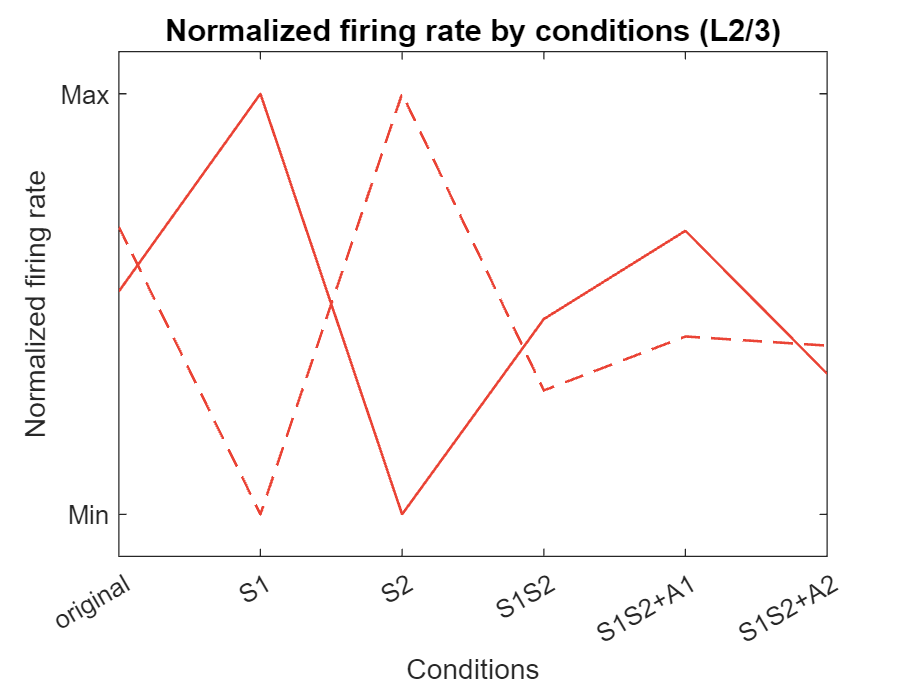

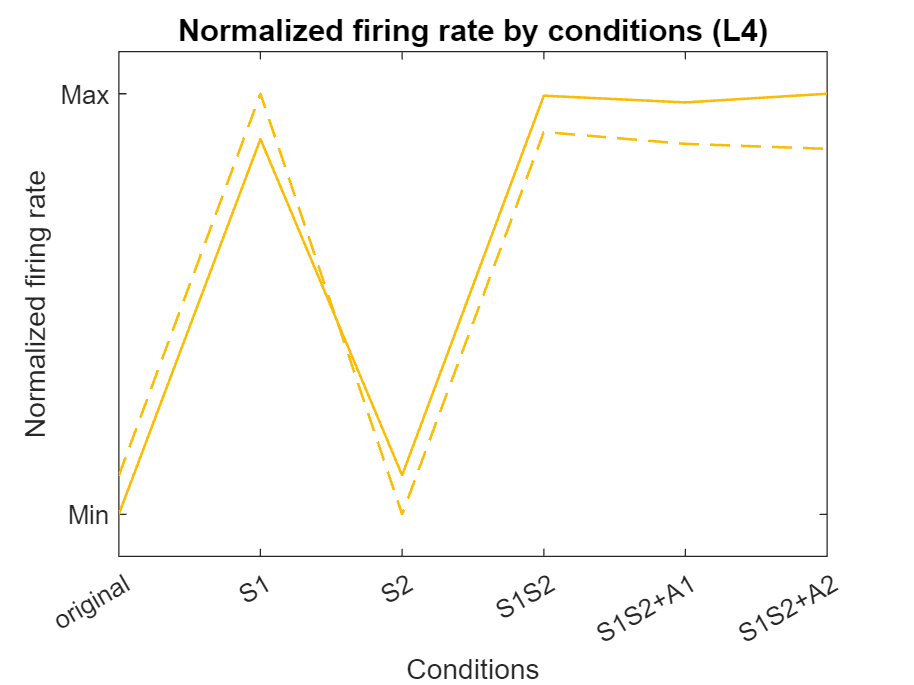

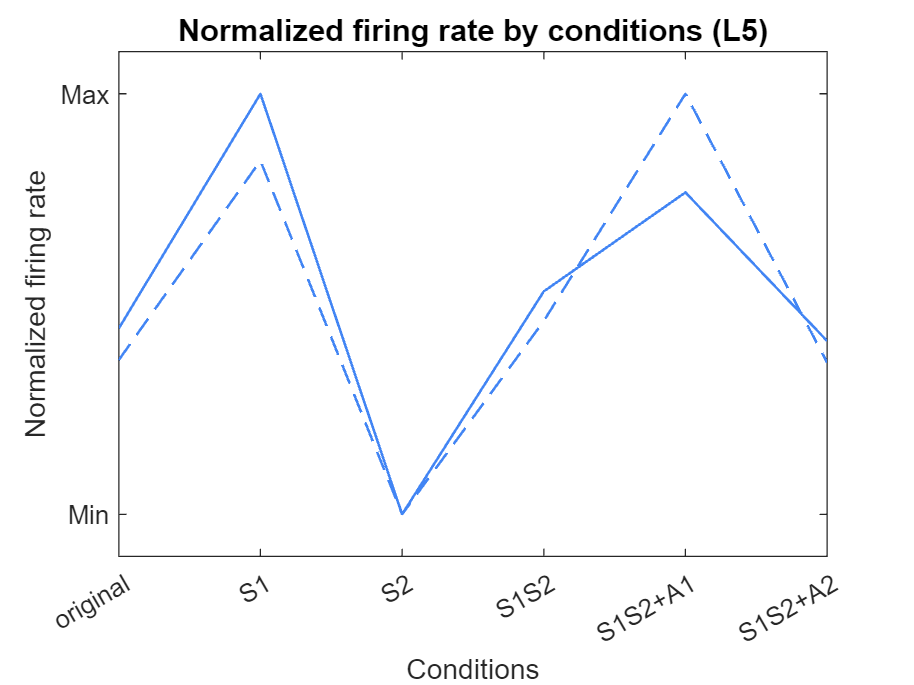

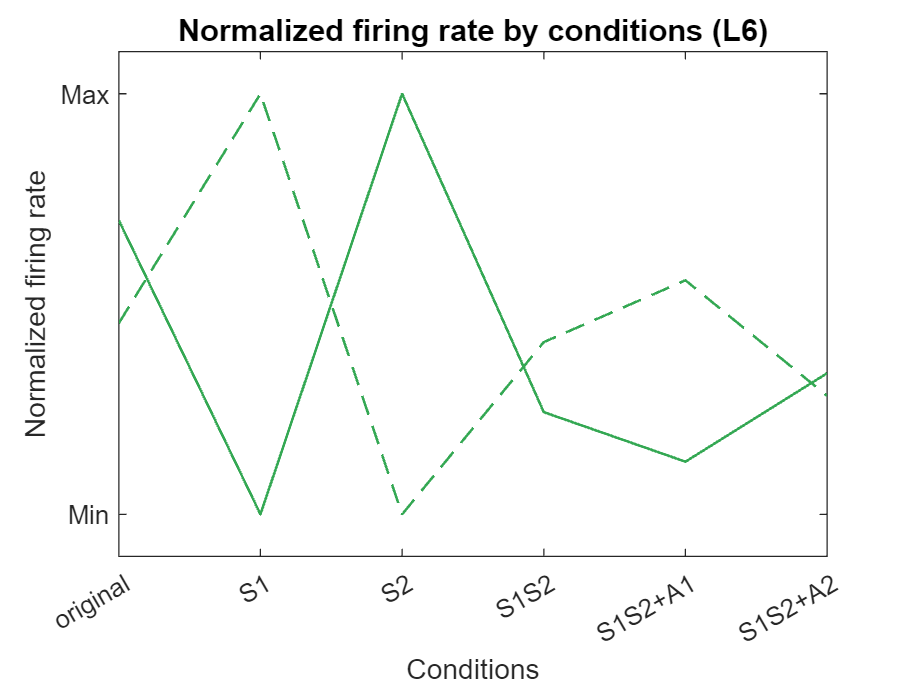


level = getLevel(r, 350000, 400000);
level_norm = normBetween01(level,2);
condax = [1 2 3 4 5 6];
for layer = 1:4
    figure();
    pop_E = (layer-1)*2 + 1;
    pop_I = layer*2;
    
    plot(condax, level_norm(pop_E,:),'Color',colors(layer), 'LineWidth',1);
    hold on;
    plot(condax, level_norm(pop_I,:),"--",'Color',colors(layer), 'LineWidth',1);

    ylabel("Normalized firing rate");
    xlabel("Conditions");
    xticks([1 2 3 4 5 6]);
    xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
    ylim([-0.1 1.1]);
    yticks([0 1]);
    yticklabels(["Min" "Max"]);
    
    title(append("Normalized firing rate by conditions (", layers(layer),")"),'FontSize',12);
    
    set(gca, 'FontName', 'Arial');
    filename = append(figpath,'cross_fr_','L',num2str(layer));
    print(filename, '-dpng', '-r600');

end

## percentage line chart filled with color by condition

## percentage line chart filled with color by Delta_E/I to 1L5E

load ../../data/PETN_0.3_0.3_0.027_0.032_Iattn_0.02.mat;

delta = linspace(0.027, 0.032, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2
delta_start = 0.027;
delta_end = 0.032;

PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_EXC = PET_tmp(:, 1:2:end);  % Extract odd columns
PET_INH = PET_tmp(:, 2:2:end);  % Extract even columns
% PET_EXC = normTo1(PET_tmp_EXC,2); 
% PET_INH = normTo1(PET_tmp_INH,2);


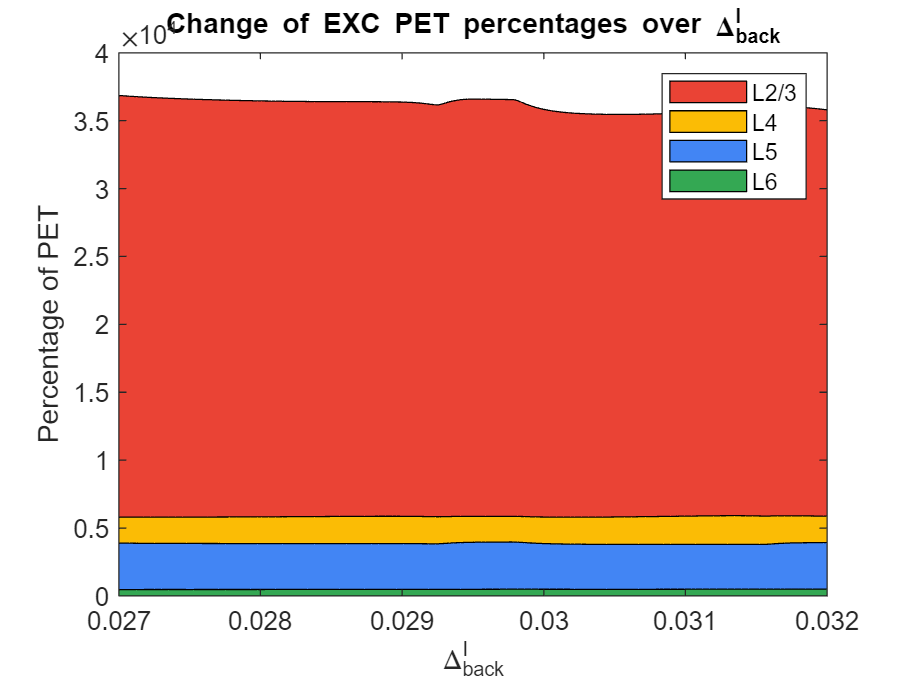

% Make the area plot fr EXC
figure();
for layer = 1:4
area(delta, PET_EXC(:,layer), 'FaceColor', colors(layer)); %,'LineStyle','none');
hold on;
end

% Label the plot
% legend('L2/3E', 'L4E', 'L5E', 'L6E');
legend(layers);
xlabel('\Delta_{back}^{I}');
ylabel('Percentage of PET');
title('Change of EXC PET percentages over \Delta_{back}^{I}');
xlim([0.027 0.032])

% ylim([-0.1 1.1]);
% yticks([0 1]);
% yticklabels(["0%" "100%"]);


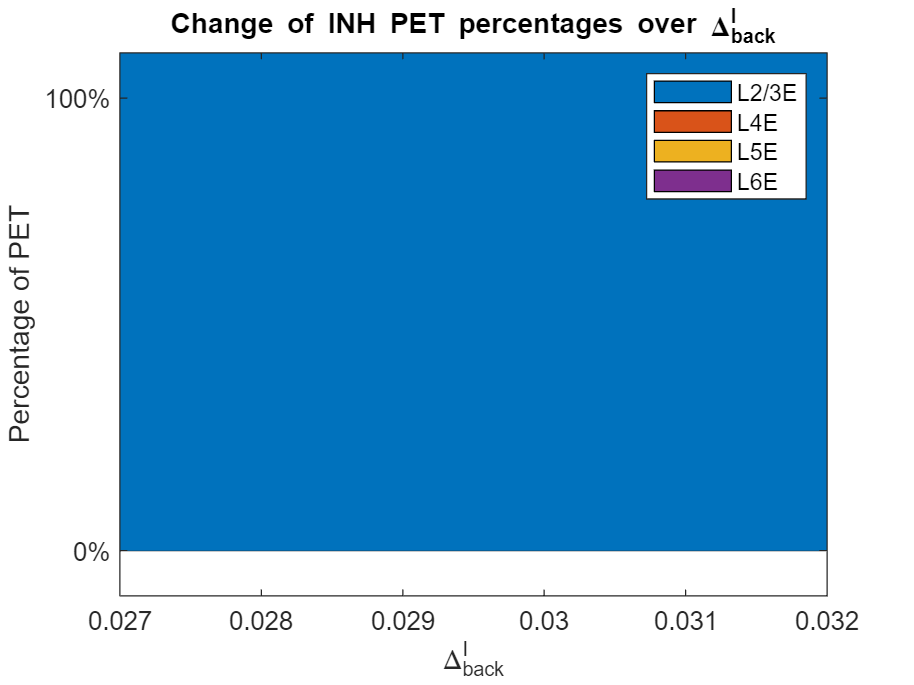

% Make the area plot for INH
figure();
area(delta, PET_INH);

% Label the plot
legend('L2/3E', 'L4E', 'L5E', 'L6E');
xlabel('\Delta_{back}^{I}');
ylabel('Percentage of PET');
title('Change of INH PET percentages over \Delta_{back}^{I}');
xlim([0.027 0.032])
ylim([-0.1 1.1]);
yticks([0 1]);
yticklabels(["0%" "100%"]);

## no area, just line EXC, no norm

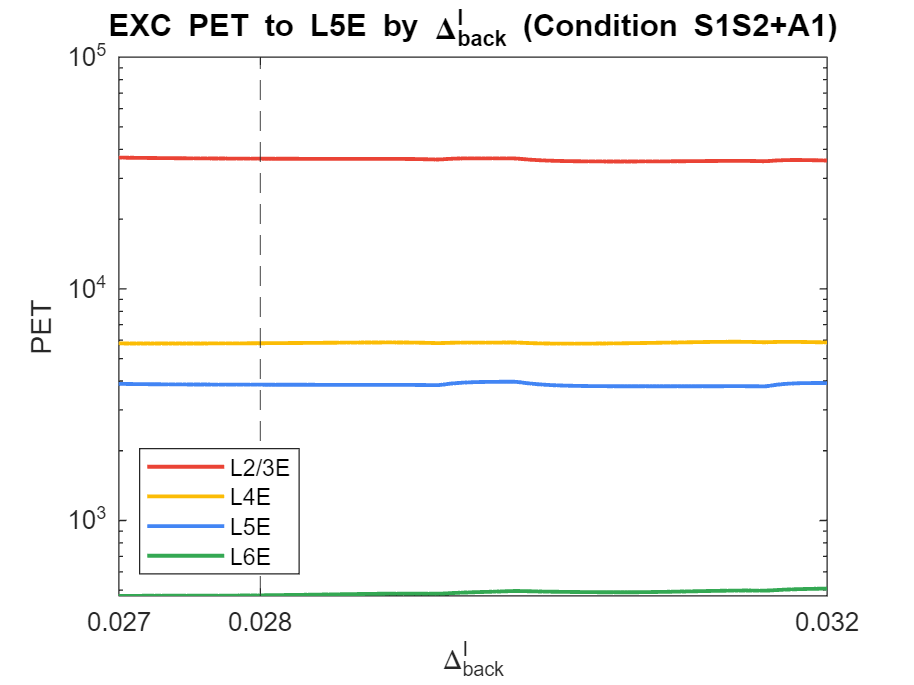

load ../../data/PETN_0.3_0.3_0.027_0.032_Iattn_0.02.mat;

delta = linspace(0.027, 0.032, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2
delta_start = 0.027;
delta_end = 0.032;

PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_EXC = PET_tmp(:, 1:2:end);  % Extract odd columns
PET_INH = PET_tmp(:, 2:2:end);  % Extract even columns

figure();
for layer = 1:4
    plot(delta, PET_EXC(:,layer), 'Color', colors(layer),'LineWidth',1.5);
    hold on;
end
xline(0.028,'LineStyle','--');

legend({'L2/3E', 'L4E', 'L5E', 'L6E'},'Location','southwest');
xlabel('\Delta_{back}^{I}');
ylabel('PET');
title('EXC PET to L5E by \Delta_{back}^{I} (Condition S1S2+A1)','FontSize',12);
xlim([0.027 0.032])
xticks([delta_start 0.028 delta_end]);

set(gca,'YScale', 'log');

set(gca, 'FontName', 'Arial');
filename = append(figpath,'PET_EXC_to_L5E_DeltaI_cond5_log');
print(filename, '-dpng', '-r600');

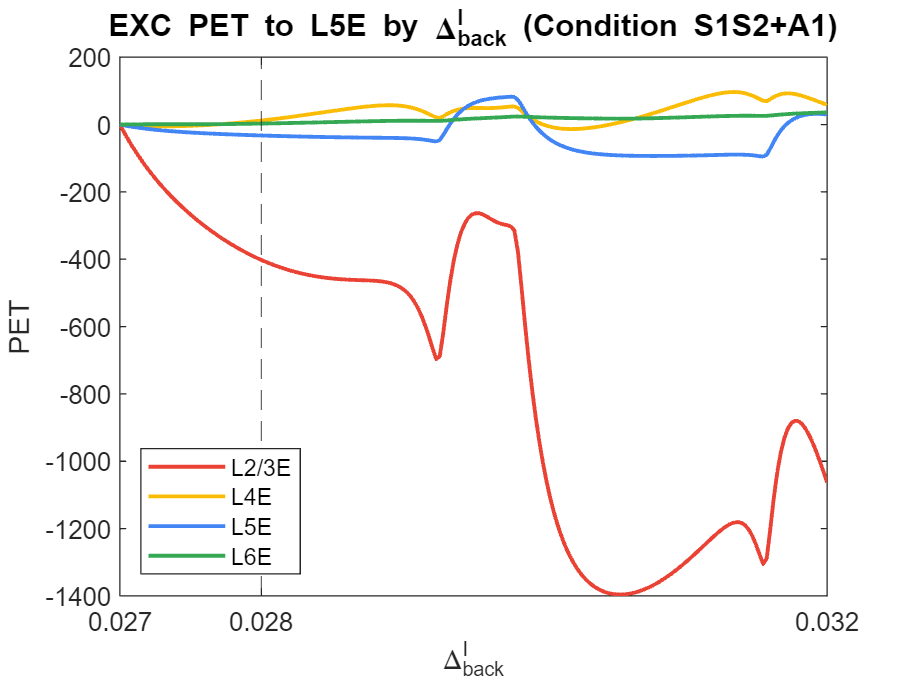

load ../../data/PETN_0.3_0.3_0.027_0.032_Iattn_0.02.mat;

delta = linspace(0.027, 0.032, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2
delta_start = 0.027;
delta_end = 0.032;

PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_EXC = PET_tmp(:, 1:2:end);  % Extract odd columns
PET_INH = PET_tmp(:, 2:2:end);  % Extract even columns

% seperate 4 y axes
figure();
for layer = 1:4
y = PET_EXC(:,layer) - PET_EXC(1,layer);
plot(delta,y,'Color',colors(layer),'LineWidth',1.5);
hold on;
end
xline(0.028,'LineStyle','--');

legend({'L2/3E', 'L4E', 'L5E', 'L6E'},'Location','southwest');
xlabel('\Delta_{back}^{I}');
ylabel('PET');
title('EXC PET to L5E by \Delta_{back}^{I} (Condition S1S2+A1)','FontSize',12);
xlim([0.027 0.032]);
xticks([delta_start 0.028 delta_end]);


set(gca, 'FontName', 'Arial');
filename = append(figpath,'PET_EXC_to_L5E_DeltaI_cond5');
print(filename, '-dpng', '-r600');

## no area, just line INH, no norm

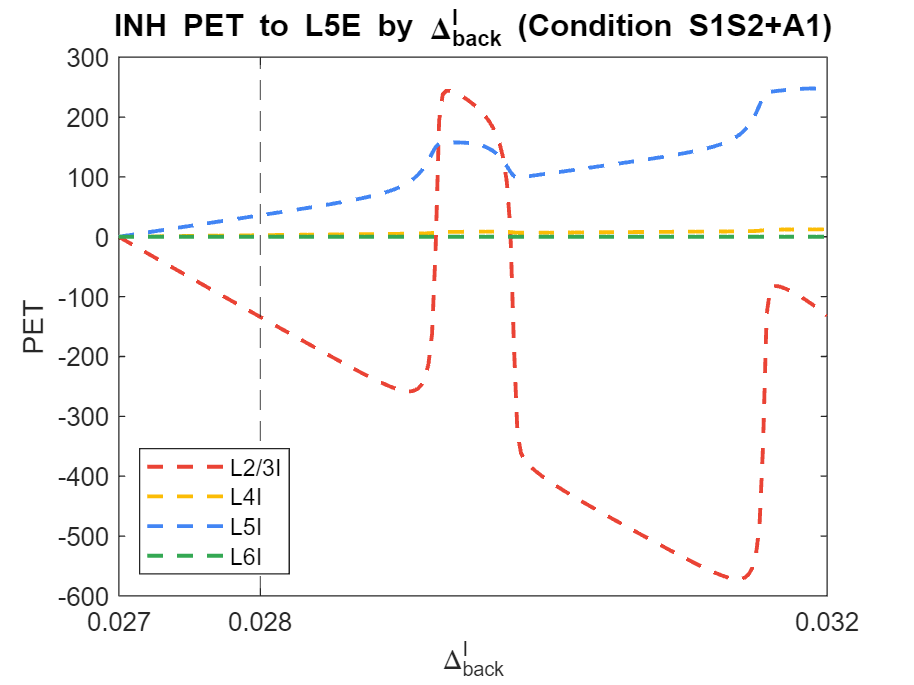

load ../../data/PETN_0.3_0.3_0.027_0.032_Iattn_0.02.mat;

delta = linspace(0.027, 0.032, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2
delta_start = 0.027;
delta_end = 0.032;

PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_EXC = PET_tmp(:, 1:2:end);  % Extract odd columns
PET_INH = PET_tmp(:, 2:2:end);  % Extract even columns

% seperate 4 y axes
figure();
for layer = 1:4
y = PET_INH(:,layer) - PET_INH(1,layer);
plot(delta,y,'Color',colors(layer),'LineStyle','--','LineWidth',1.5);
hold on;
end
xline(0.028,'LineStyle','--');


legend({'L2/3I', 'L4I', 'L5I', 'L6I'},'Location','southwest');
xlabel('\Delta_{back}^{I}');
ylabel('PET');
title('INH PET to L5E by \Delta_{back}^{I} (Condition S1S2+A1)','FontSize',12);
xlim([0.027 0.032]);
xticks([delta_start 0.028 delta_end]);

set(gca, 'FontName', 'Arial');
filename = append(figpath,'PET_INH_to_L5E_DeltaI_cond5');
print(filename, '-dpng', '-r600');

## Normalized change of PET by Delta

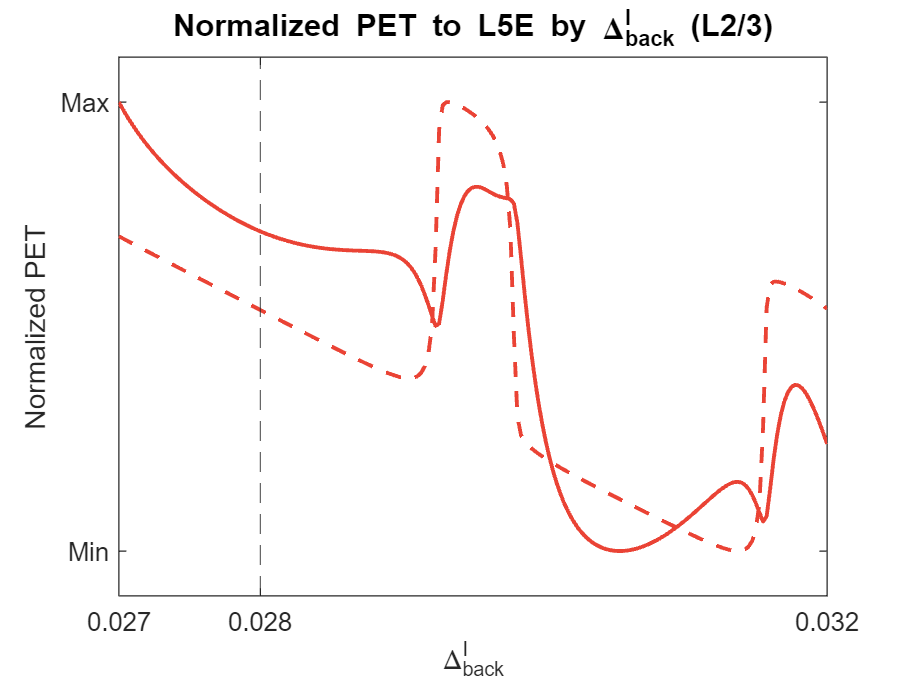

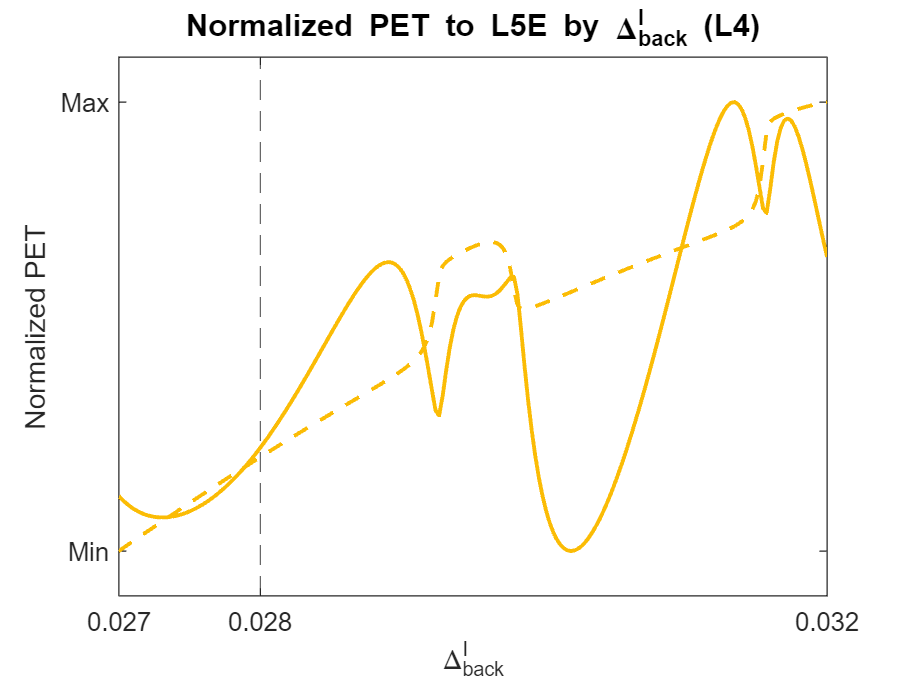

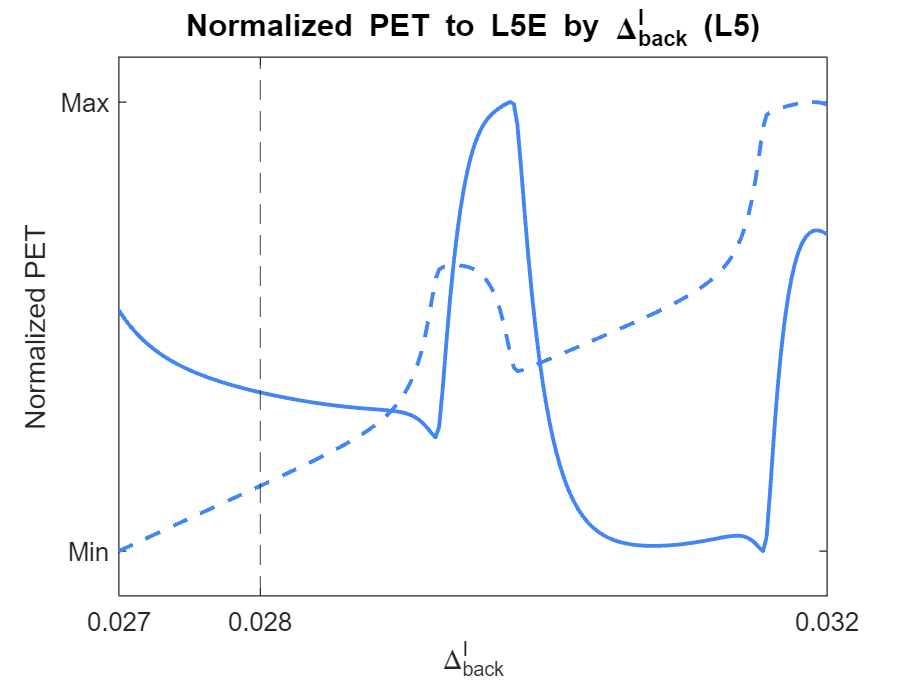

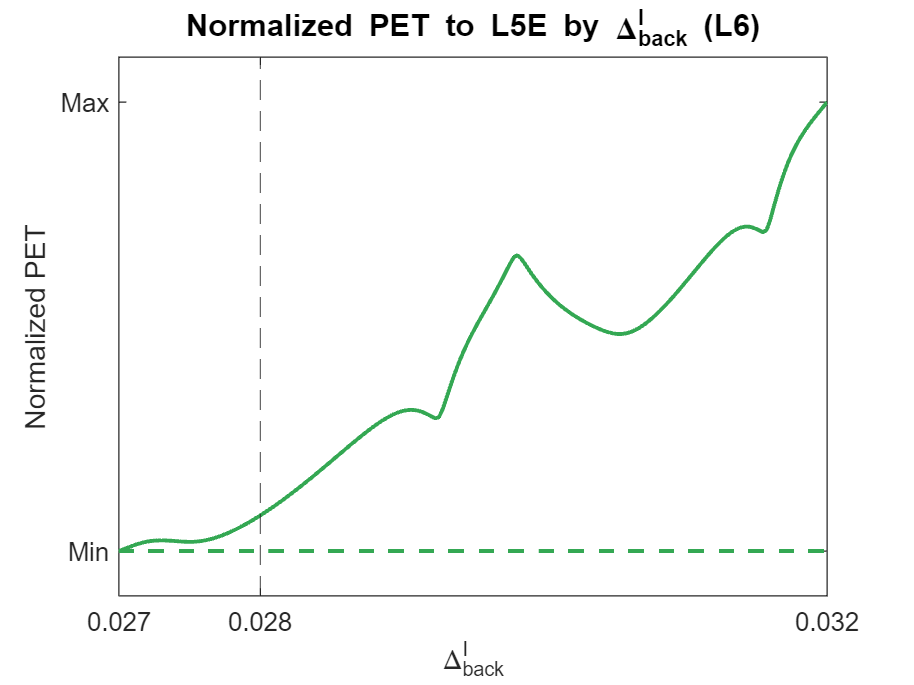

load ../../data/PETN_0.3_0.3_0.027_0.032_Iattn_0.02.mat;

delta_start = 0.027;
delta_end = 0.032;
delta = linspace(delta_start, delta_end, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2
PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_normed = normBetween01(PET_tmp, 1);

for layer = 1:4
    figure();
    pop_E = (layer-1)*2 + 1;
    pop_I = layer*2;
    
    plot(delta, PET_normed(:,pop_E),'Color',colors(layer), 'LineWidth',1.5);
    hold on;
    plot(delta, PET_normed(:,pop_I),"--",'Color',colors(layer), 'LineWidth',1.5);
    xline(0.028,'LineStyle','--');

    ylabel("Normalized PET");
    xlabel("\Delta_{back}^{I}");
    xlim([delta_start delta_end]);
    xticks([delta_start 0.028 delta_end]);
    % xticklabels(["x" "+"]);
    ylim([-0.1 1.1]);
    yticks([0 1]);
    yticklabels(["Min" "Max"]);
    
    title(append("Normalized PET to L5E by \Delta_{back}^{I} (", layers(layer),")"),'FontSize',12);
    
    set(gca, 'FontName', 'Arial');
    filename = append(figpath,'PET_normed_Delta_I_cond5_','L',num2str(layer));
    print(filename, '-dpng', '-r600');

end

## Normalized PET EXC by Delta_I

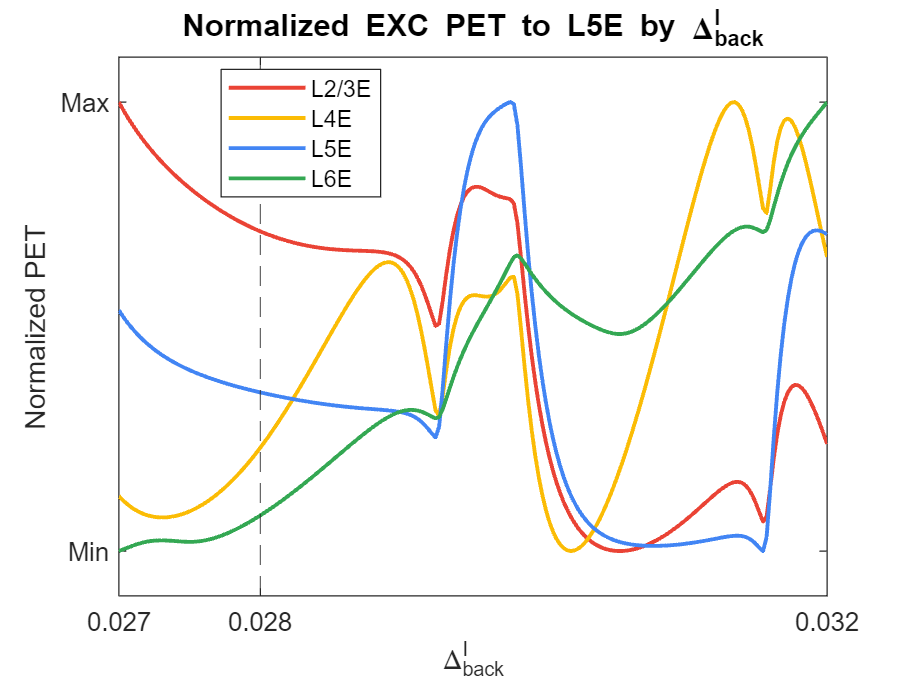

load ../../data/PETN_0.3_0.3_0.027_0.032_Iattn_0.02.mat;

delta_start = 0.027;
delta_end = 0.032;
delta = linspace(delta_start, delta_end, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2
PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_normed = normBetween01(PET_tmp, 1);

figure();
for layer = 1:4

    pop_E = (layer-1)*2 + 1;
    pop_I = layer*2;
    
    plot(delta, PET_normed(:,pop_E),'Color',colors(layer), 'LineWidth',1.5);
    hold on;

end

    xline(0.028,'LineStyle','--');

    ylabel("Normalized PET");
    xlabel("\Delta_{back}^{I}");
    xlim([delta_start delta_end]);
    xticks([delta_start 0.028 delta_end]);
    % xticklabels(["x" "+"]);
    ylim([-0.1 1.1]);
    yticks([0 1]);
    yticklabels(["Min" "Max"]);
    legend({'L2/3E', 'L4E', 'L5E', 'L6E'},'Location','northwest');
    legend("Position", [0.24211,0.71411,0.17479,0.18399])

    title(append("Normalized EXC PET to L5E by \Delta_{back}^{I}"),'FontSize',12);
    
    set(gca, 'FontName', 'Arial');
    filename = append(figpath,'EXC_PET_normed_Delta_I_cond5_');
    print(filename, '-dpng', '-r600');

## Normalized PET INH by Delta_I

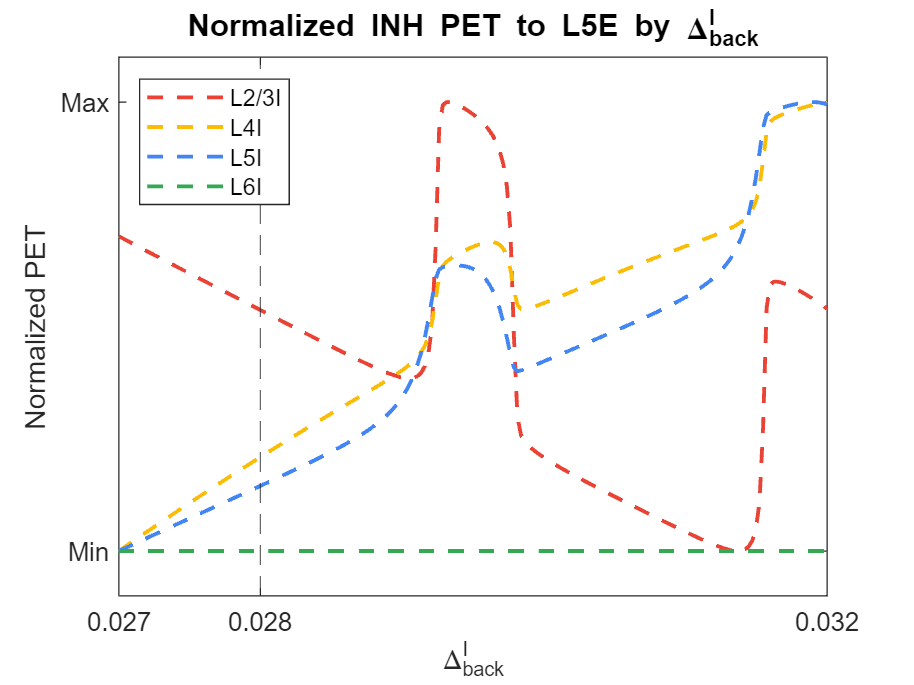

load ../../data/PETN_0.3_0.3_0.027_0.032_Iattn_0.02.mat;

delta_start = 0.027;
delta_end = 0.032;
delta = linspace(delta_start, delta_end, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2
PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_normed = normBetween01(PET_tmp, 1);

figure();
for layer = 1:4

    pop_E = (layer-1)*2 + 1;
    pop_I = layer*2;
    
    plot(delta, PET_normed(:,pop_I),"--",'Color',colors(layer), 'LineWidth',1.5);
    hold on;

end

    xline(0.028,'LineStyle','--');

    ylabel("Normalized PET");
    xlabel("\Delta_{back}^{I}");
    xlim([delta_start delta_end]);
    xticks([delta_start 0.028 delta_end]);
    % xticklabels(["x" "+"]);
    ylim([-0.1 1.1]);
    yticks([0 1]);
    yticklabels(["Min" "Max"]);
    legend({'L2/3I', 'L4I', 'L5I', 'L6I'},'Location','northwest');
    % legend("Position", [0.24211,0.71411,0.17479,0.18399])

    title(append("Normalized INH PET to L5E by \Delta_{back}^{I}"),'FontSize',12);
    
    set(gca, 'FontName', 'Arial');
    filename = append(figpath,'INH_PET_normed_Delta_I_cond5_');
    print(filename, '-dpng', '-r600');

## Delta_E

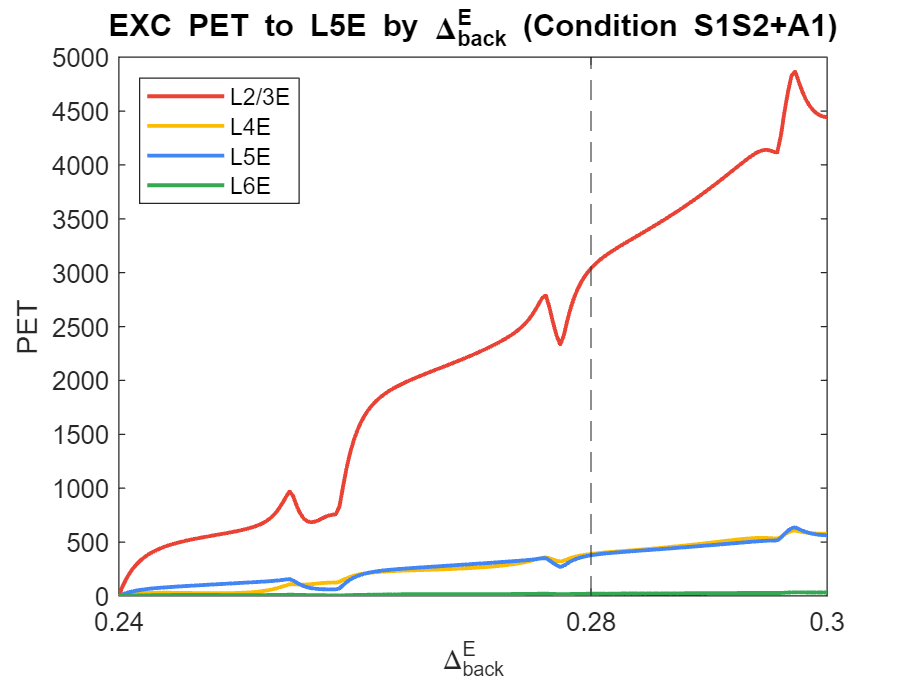

load ../../data/PETN_0.24_0.3_0.027_0.027_Iattn_0.02.mat

delta_start = 0.24;
delta_end = 0.3;

delta = linspace(delta_start, delta_end, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2

PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_EXC = PET_tmp(:, 1:2:end);  % Extract odd columns
PET_INH = PET_tmp(:, 2:2:end);  % Extract even columns

% seperate 4 y axes
figure();
for layer = 1:4
y = PET_EXC(:,layer) - PET_EXC(1,layer);
plot(delta,y,'Color',colors(layer),'LineWidth',1.5);
hold on;
end
xline(0.28,'LineStyle','--');

legend({'L2/3E', 'L4E', 'L5E', 'L6E'},'Location','northwest');
xlabel('\Delta_{back}^{E}');
ylabel('PET');
title('EXC PET to L5E by \Delta_{back}^{E} (Condition S1S2+A1)','FontSize',12);
xlim([delta_start delta_end]);
xticks([delta_start 0.28 delta_end]);


set(gca, 'FontName', 'Arial');
filename = append(figpath,'PET_EXC_to_L5E_DeltaE_cond5');
print(filename, '-dpng', '-r600');

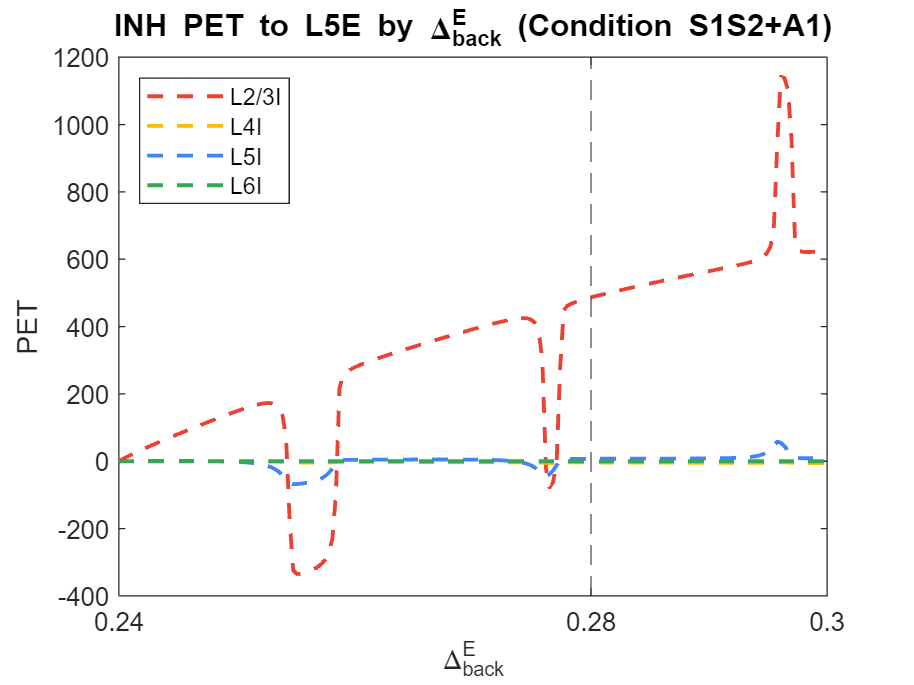

load ../../data/PETN_0.24_0.3_0.027_0.027_Iattn_0.02.mat

delta_start = 0.24;
delta_end = 0.3;

delta = linspace(delta_start, delta_end, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2

PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_EXC = PET_tmp(:, 1:2:end);  % Extract odd columns
PET_INH = PET_tmp(:, 2:2:end);  % Extract even columns

% seperate 4 y axes
figure();
for layer = 1:4
y = PET_INH(:,layer) - PET_INH(1,layer);
plot(delta,y,'Color',colors(layer),'LineStyle','--','LineWidth',1.5);
hold on;
end
xline(0.28,'LineStyle','--');

legend({'L2/3I', 'L4I', 'L5I', 'L6I'},'Location','northwest');
xlabel('\Delta_{back}^{E}');
ylabel('PET');
title('INH PET to L5E by \Delta_{back}^{E} (Condition S1S2+A1)','FontSize',12);
xlim([delta_start delta_end]);
xticks([delta_start 0.28 delta_end]);


set(gca, 'FontName', 'Arial');
filename = append(figpath,'PET_INH_to_L5E_DeltaE_cond5');
print(filename, '-dpng', '-r600');

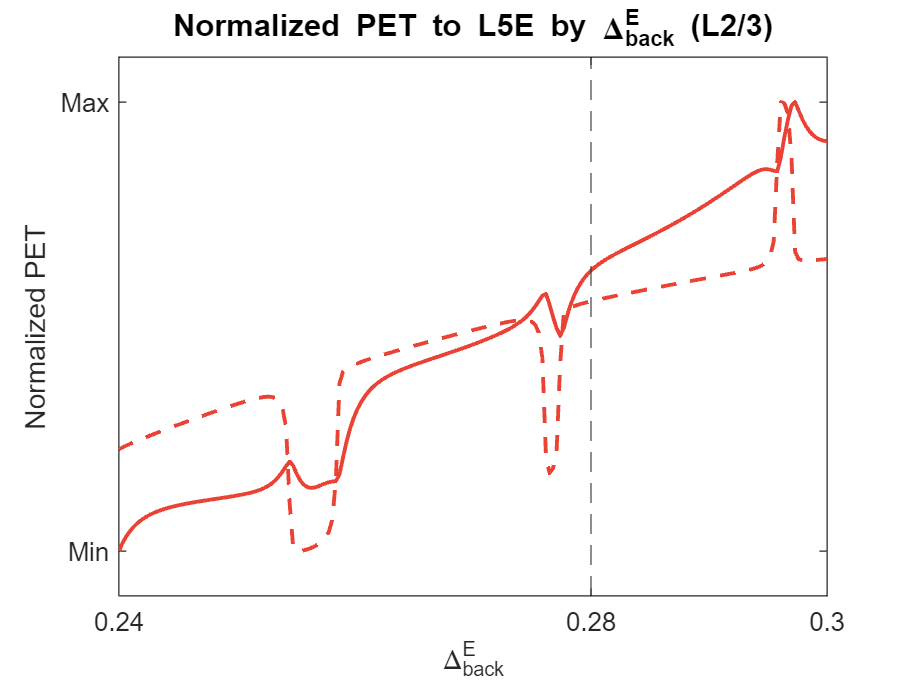

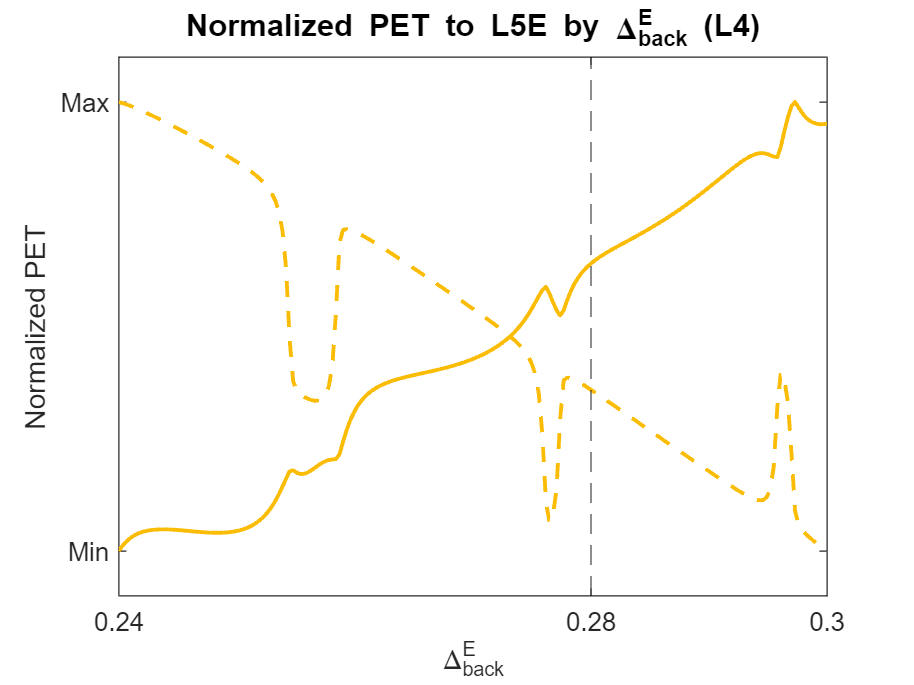

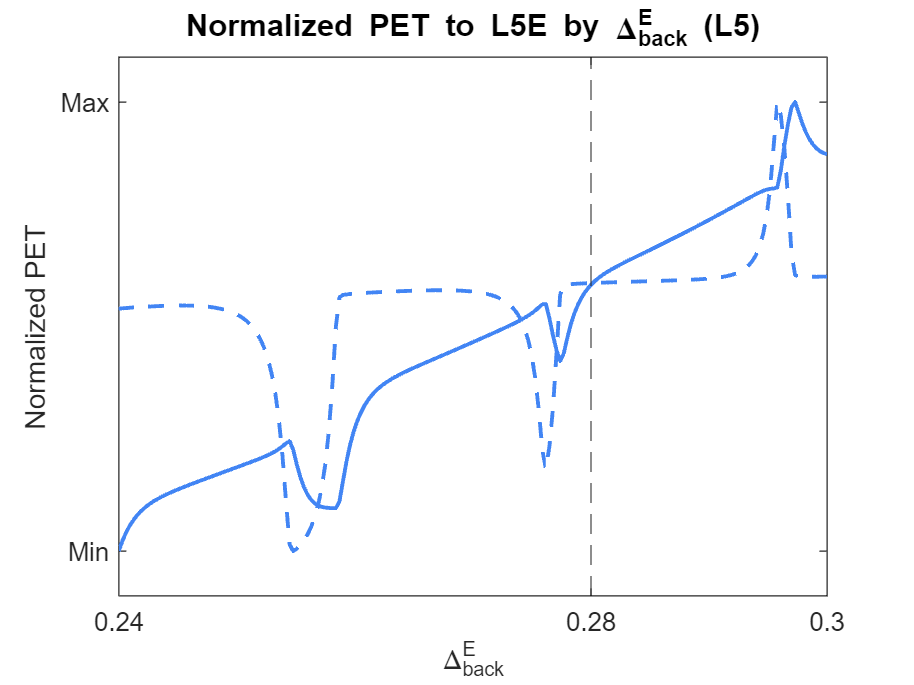

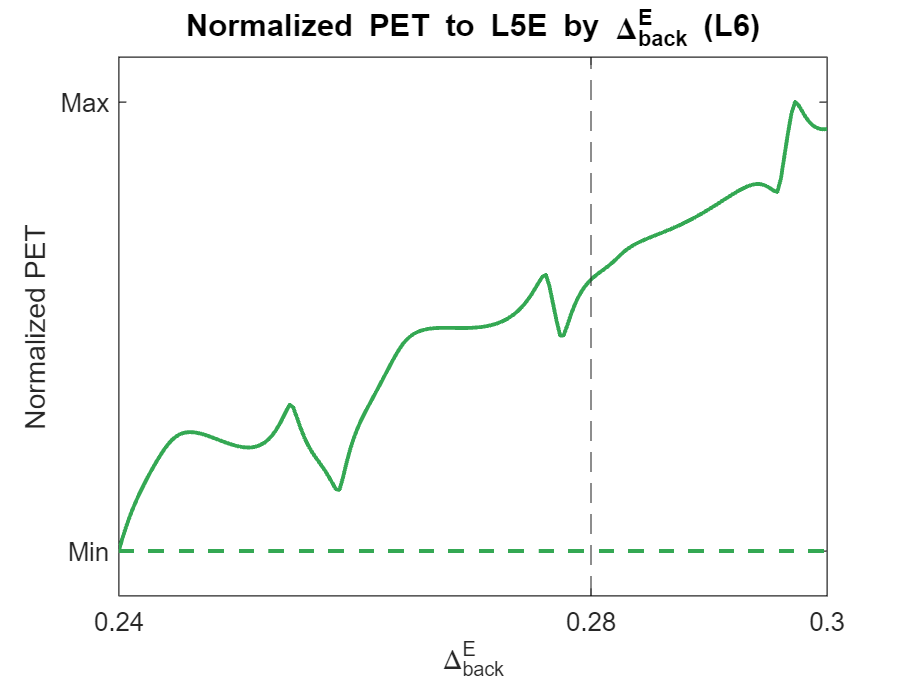

load ../../data/PETN_0.24_0.3_0.027_0.027_Iattn_0.02.mat

delta_start = 0.24;
delta_end = 0.3;

delta = linspace(delta_start, delta_end, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2
PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_normed = normBetween01(PET_tmp, 1);

for layer = 1:4
    figure();
    pop_E = (layer-1)*2 + 1;
    pop_I = layer*2;
    
    plot(delta, PET_normed(:,pop_E),'Color',colors(layer), 'LineWidth',1.5);
    hold on;
    plot(delta, PET_normed(:,pop_I),"--",'Color',colors(layer), 'LineWidth',1.5);
    xline(0.28,'LineStyle','--');

    ylabel("Normalized PET");
    xlabel("\Delta_{back}^{E}");
    xlim([delta_start delta_end]);
    xticks([delta_start 0.28 delta_end]);
    
    ylim([-0.1 1.1]);
    yticks([0 1]);
    yticklabels(["Min" "Max"]);
    
    title(append("Normalized PET to L5E by \Delta_{back}^{E} (", layers(layer),")"),'FontSize',12);
    
    set(gca, 'FontName', 'Arial');
    filename = append(figpath,'PET_normed_Delta_E_cond5_','L',num2str(layer));
    print(filename, '-dpng', '-r600');

end

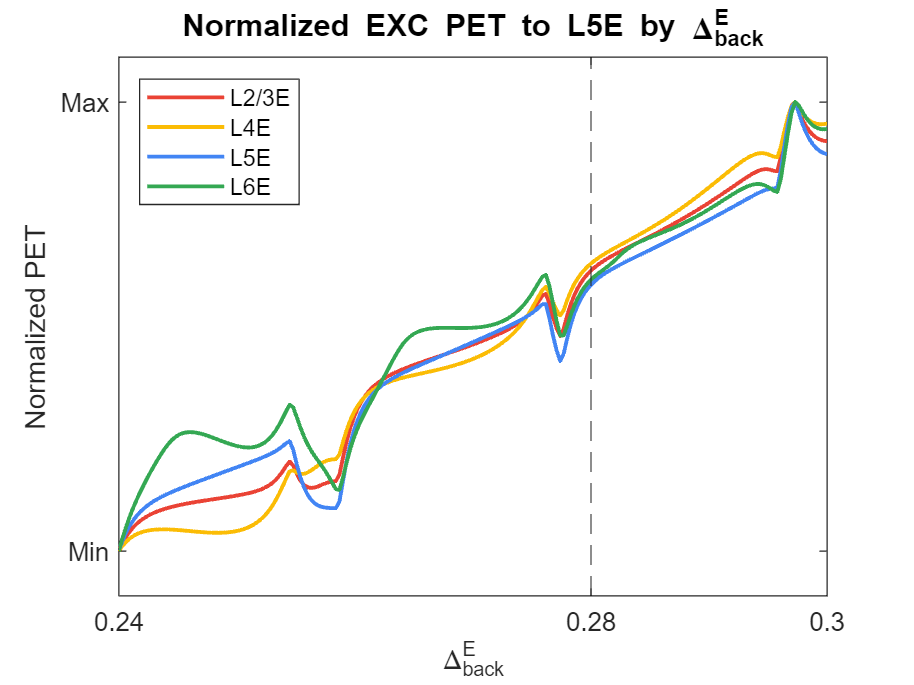

load ../../data/PETN_0.24_0.3_0.027_0.027_Iattn_0.02.mat

delta_start = 0.24;
delta_end = 0.3;

delta = linspace(delta_start, delta_end, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2
PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_normed = normBetween01(PET_tmp, 1);

figure();
for layer = 1:4

    pop_E = (layer-1)*2 + 1;
    pop_I = layer*2;
    
    plot(delta, PET_normed(:,pop_E),'Color',colors(layer), 'LineWidth',1.5);
    hold on;

end

    xline(0.28,'LineStyle','--');

    ylabel("Normalized PET");
    xlabel("\Delta_{back}^{E}");
    xlim([delta_start delta_end]);
    xticks([delta_start 0.28 delta_end]);
    % xticklabels(["x" "+"]);
    ylim([-0.1 1.1]);
    yticks([0 1]);
    yticklabels(["Min" "Max"]);
    legend({'L2/3E', 'L4E', 'L5E', 'L6E'},'Location','northwest');

    title(append("Normalized EXC PET to L5E by \Delta_{back}^{E}"),'FontSize',12);
    
    set(gca, 'FontName', 'Arial');
    filename = append(figpath,'EXC_PET_normed_Delta_E_cond5_');
    print(filename, '-dpng', '-r600');

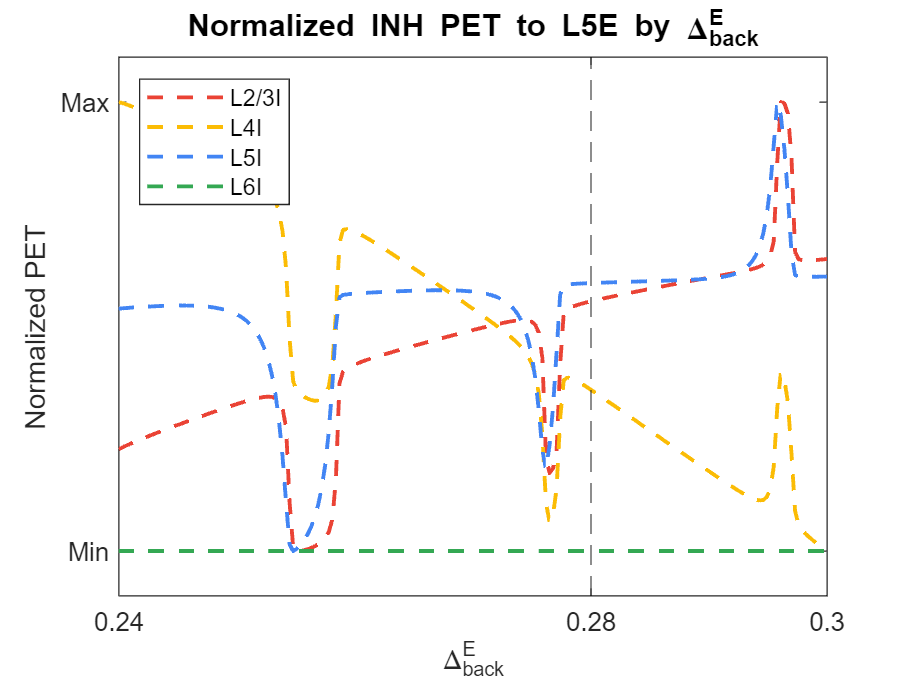

load ../../data/PETN_0.24_0.3_0.027_0.027_Iattn_0.02.mat

delta_start = 0.24;
delta_end = 0.3;

delta = linspace(delta_start, delta_end, size(PET,1));
pop = 5;
cond = 5; % 1-original, 2-S1, 3-S2, 4-S1S2, 5-S1S2+A1, 6-S1S2+A2
PET_tmp = squeeze(PET(:,pop,1:8,cond));
PET_normed = normBetween01(PET_tmp, 1);

figure();
for layer = 1:4

    pop_E = (layer-1)*2 + 1;
    pop_I = layer*2;
    
    plot(delta, PET_normed(:,pop_I),"--",'Color',colors(layer), 'LineWidth',1.5);
    hold on;

end

    xline(0.28,'LineStyle','--');

    ylabel("Normalized PET");
    xlabel("\Delta_{back}^{E}");
    xlim([delta_start delta_end]);
    xticks([delta_start 0.28 delta_end]);
    
    ylim([-0.1 1.1]);
    yticks([0 1]);
    yticklabels(["Min" "Max"]);
    legend({'L2/3I', 'L4I', 'L5I', 'L6I'},'Location','northwest');
    % legend("Position", [0.24211,0.71411,0.17479,0.18399])

    title(append("Normalized INH PET to L5E by \Delta_{back}^{E}"),'FontSize',12);
    
    set(gca, 'FontName', 'Arial');
    filename = append(figpath,'INH_PET_normed_Delta_E_cond5_');
    print(filename, '-dpng', '-r600');